## Customized canopy and terrain height calculation

The current version (Version 5) of ATL08 product provides canopy and terrain heights in fixed 20 m and 100 m segments. The xATLy toolbox extends these options by allowing you to generate terrain and canopy height estimates at preferred segment lengths while controlling the number of points to use in your calculations to support topographic modeling and vegetation structure characterization. 

In this notebook, we will demonstrate how to use the toolbox to calculate canopy and terrain heights in custom segment lengths.

- Creating Atl03, Atl08 and ground track objects

- Steps for customized calculation of  canopy and terrain heights

- Generating customized segment polygons

- Concluding remarks

### Create Atl03, Atl08 and ground track objects

In this exercise, you will use an ATL03/ATL08 granule acquired in 2019 across an area in north-western Zambia.You may subsitute it with granule of your choice but remember to update the file paths below.

Create `Atl03` and `Atl08` objects using filepath provided below 

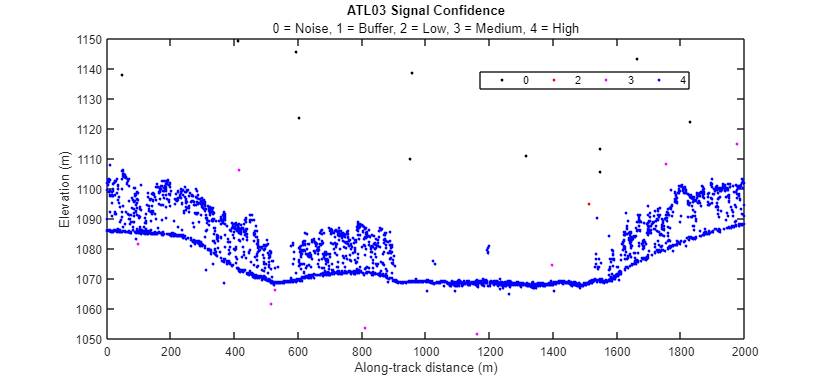

atl03path = "./data/ATL03_20190603025340_10050314_002_01.h5"; % ATL03 filepath
atl08path = "./data/ATL08_20190603025340_10050314_002_01.h5"; % ATL08 filepath

% create an Atl03 and Atl08 objects
a3 = Atl03(atl03path);
a8 = Atl08(atl08path);

% create ground track object. Here we select the srtong beeam from middle
% ground track pair, gt2l. To see available you may use a3.gettracklist() 
% or a8.gettracklist();% The track you choose must be available in Atl03 
% and Atl08 objects

gt = gtrack('gt1l',a3,a8);

% visualize section of the data
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.7]);

% plot raw point cloud with signal confidence rendering 
atdplot(gt,'s',[],atdlim) % group points by signal confidence, use default colors
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

### Calculate canopy and terrain heights

Calculating canopy and terrain heights usually involves a number of steps including:

- Retrieving a classified point cloud

- Fitting the ground level,

- Aboveground height normalization, and 

- Canopy and terrain metric calculation. 

The first three steps above can be done using one function call, i.e. through the `getnormalizedpc() `method`, `but for better appreciation of the various parameters being used, a step-by-step approach is presented below.

#### **1**. Retrieve classified point cloud using `getclassedpc` method. 

The `getclassedpc `method is meant to retrieve a classified point cloud by joining ATL08 photon classes (classed_pc_flag), with the raw ATL03 point cloud. Apart from Atl03 and Atl08 objects, it takes two additional parameters:  

- `inc_these_seg_attrib`, which allows inclusion ATL08 segment level attributes in the point cloud,

- `clip_aoi`, which enables clipping of the returned point cloud to an area of interest. 

In this demonstration, we will include the msw_flag and night_flag to provide further information on atmospheric scattering and night/day acquisition. 

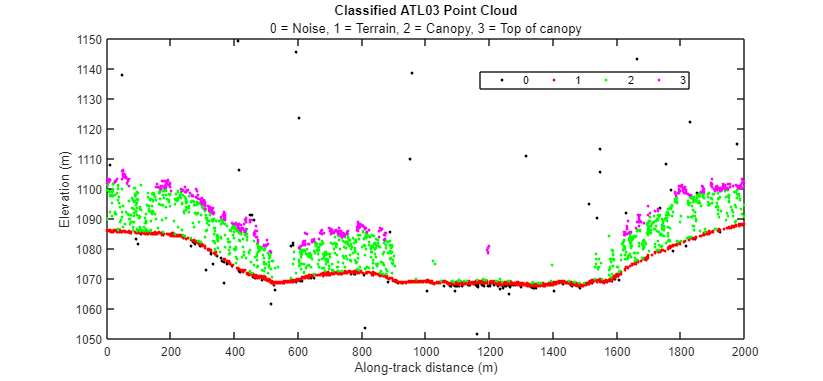

inc_these_seg_attrib = {'msw_flag','night_flag'};
pc = getclassedpc(gt,inc_these_seg_attrib);% No clipping to area of interest

% visualize section of the data
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.7]);

% plot classified point cloud 
plothis = 'c'; % photn class
colors = 'krgm'; % black for noise,red = terrain etc
excludenoisepts = false; % includes noise points

atdplot(gt,plothis, colors, atdlim, excludenoisepts) 
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

#### **2. **Fit ground level using the `fitgroundmodel` function. 

ICESat-2 measures along tracks, so terrain surfaces are modeled as 1d curves in the xATLy toolbox as outlined below.

- Terrain points extracted from the classified point cloud are used to create curves, with along-track distance and elevation as x- and y-axis values, respectively.

- To generate smoother curves through the points, terrain points are binned at fixed interval distances.

- The median elevation value in each bin is taken as the representative elevation value.

- A curve is then interpolated to connect all the bin elevations using a specified interpolation method.

The `fitgroundmodel` in the xATLy toolbox is used to fit a curve to the terrain points outputting a curve fit object/function and the ground points used in the fitting. 

% fit ground level
grndInterval = 10; % binning distance
interpolatemethod = 'smoothingspline';%'other options 'linearinterp','cubicspline';
robustfit = false; % no robust fitting using RANSAC. This is still experimnetal
[grndFunc, gpts] = fitgroundmodel(pc,grndInterval,interpolatemethod,robustfit);

The following lines of code plots the point cloud together with the fitted ground curve. We use tiled layout to show zoomed views of two sections of the data to clearly show details on the binning and fitting.

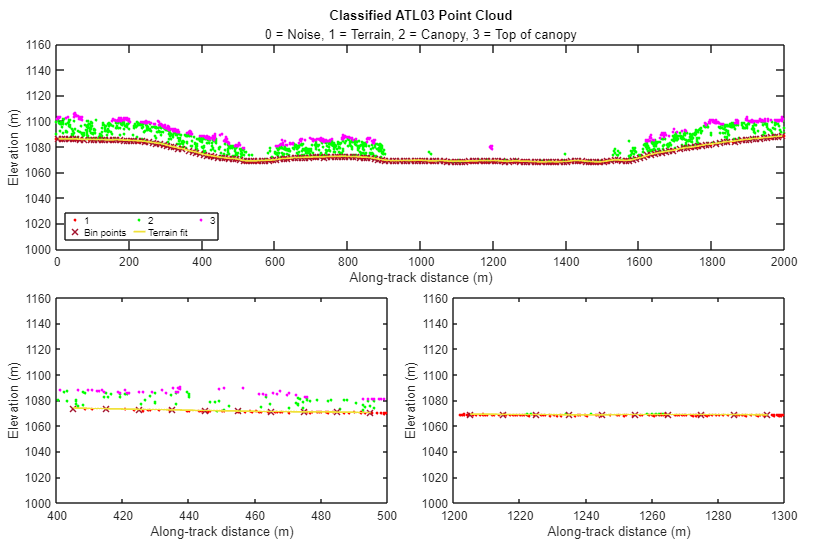

% Visualize fitted ground surface
figure('units','normalized','outerposition',[0.0 0.0 0.85 1]);
t = tiledlayout(2,2);

nexttile(1,[1,2])
atdlim = [0,2000];
mksize =  7;
plothis = 'c';
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.DisplayName = 'Bin points';
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.DisplayName = 'Terrain fit';
cg.Color = [ 0.9412,0.8824,0.2275];
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
lg2 = legend('Orientation','horizontal','Location','southwest','NumColumns',3,'FontSize',8);
lg2.ItemTokenSize(1) = 10;
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off

nexttile
atdlim = [400,500];
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.Color = [ 0.9412,0.8824,0.2275];
lg2 = legend('off');

title('')
subtitle('')
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off

nexttile
atdlim = [1200,1300];
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.Color = [ 0.9412,0.8824,0.2275];
lg2 = legend('off');
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
title('')
subtitle('')
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off
t.TileSpacing = 'compact';
t.Padding = 'compact';

#### 3. Normalize point cloud using `normalizepts` function

The `normalizepts `function uses the fitted ground curve model to estimate the ground level at each point and then substracts it from the point elevation to get aboveground level heights. Ponts below the fitted ground curve will have negative aboveground heights. You have the option to remove or keep points with negative heights using the `removeptsbelow `as demostrated below.

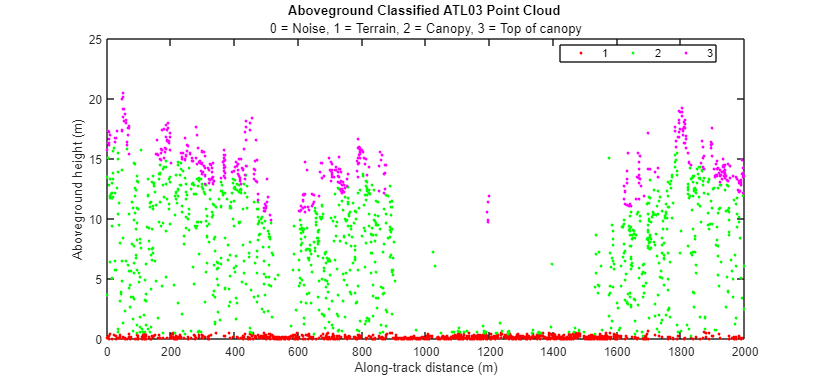

removeptsbelow = true; % gets rid of any point below fitted ground level
npc = normalizepts(pc,grndFunc, removeptsbelow);

% Visualize output
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.7]);

% plot classified point cloud 
plothis = 'n'; % photn class
colors = 'rgm'; % black for noise,red = terrain etc
excludenoisepts = true; % includes noise points

atdplot(gt,plothis, colors, atdlim, excludenoisepts) 
box on
xlim([atdlim(1),atdlim(2)])
ylim([0,25])

#### 4. Calculate canopy and terrain height using the h`metrics` function

The `hmetrics` calculates canopy and terrain metrics over each segment from normalized point cloud data. You have the option to set a segment length and minimum number of points for a valid calculation. Optionally, you can include multiple canopy height percentiles and control the minimum allowable canopy height.

% calculation parameters
segLength = 30; % use 30 m segment length
canopy_percentiles = [50,98]; % calculate 50th and 98th canopy height percentiles
minpts = 9; % set min number of points for valid calculation
min_h = 2; % set min canopy height returned
includeground = true; % includes ground points in canopy height percentile calculation

% calculate canopy and terrain heights
cH = hmetrics(npc, segLength,canopy_percentiles,minpts,min_h, includeground);

% display first 5 rows, limt columns for space to:
% 1:4 -> seg_id, seg_atd, seg_lon, seg_lat
% 9:11 - > seg_npts, seg_ca_pts, seg_te_pts
% 17 -> h_ca_p98 (98th percentile canopy height)
disp(cH(1:5,[1:4,9:11,17])) 

    seg_id    seg_atd    seg_lon    seg_lat    seg_npts    seg_ca_pts    seg_te_pts    h_ca_p98
    ______    _______    _______    _______    ________    __________    __________    ________

      1          15      23.802     -13.715       44           34            10         17.359 
      2          45      23.802     -13.715       41           31            10         20.531 
      3          75      23.802     -13.715       41           36             5         17.994 
      4         105      23.802     -13.715       49           31            18         15.796 
      5         135      23.802     -13.714       49           33            16         13.609 



By default the function includes the center segment coordinates (seg_lat/seg_lon) together with coordinates defining the beginning (seg_lat_beg/seg_lon_beg) and end (seg_lat_end/seg_lon_end) of the segment. The output table also contains the number of points in the segment (seg_npts), which is broken down into terrain (seg_te_pts), off-terrain canopy (seg_ca_pts). Other defaults include min, mean, max and standard deviation for canopy and terrain heights.

The figure below shows normalized point cloud data overlain with the calculated 98th percentile canopy height

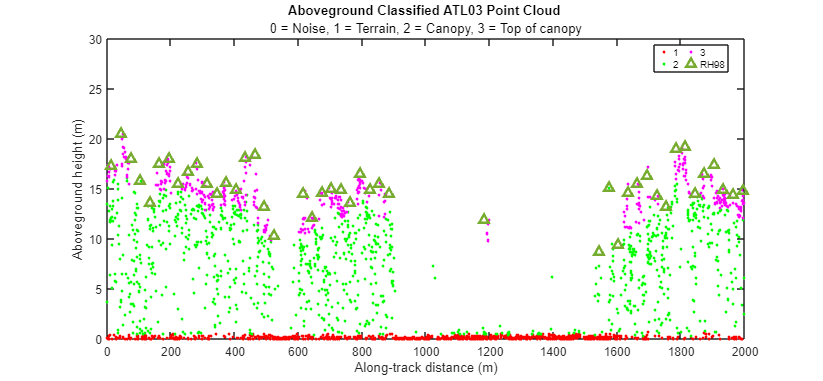

% visualize output
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.2 0.0 0.85 0.7]);

% plot classified point cloud 
plothis = 'n'; % photn class
colors = 'rgm'; % black for noise,red = terrain etc
excludenoisepts = true; % includes noise points
% normalized point cloud
atdplot(npc,plothis, colors, atdlim, excludenoisepts) 
box on

% overlay with calculated 98th percentile height
hold on
clr = [0.4667 0.6745 0.1882];
ch = 'RH98'; % 98th percentile height;
tf2 = and(cH.seg_atd >= atdlim(1), cH.seg_atd <= atdlim(2));
plot(cH.seg_atd(tf2),cH.h_ca_p98(tf2),'^','Color',clr,...
                'MarkerSize',7,'LineWidth',2,'DisplayName',ch)
hold off

lg3 = legend('Orientation','vertical','Location','best','NumColumns',2,'FontSize',8);
lg3.ItemTokenSize(1) = 10;
xlim([atdlim(1),atdlim(2)])
ylim([0,30])

#### Combining steps 1 -3

In case you are only interested in calculating heights, steps 1 - 3 can be combined as follows:

% parameters
inc_these_seg_attrib = {'msw_flag','night_flag'};
clip_aoi = []; % no clipping enabled
grndInterval = 10;
interpolatemethod = 'smoothingspline';
robustfit = false;
removeptsbelow = true;

% get normalized points directly
npc = gt.getnormalizedpc(inc_these_seg_attrib, clip_aoi, grndInterval,...
                interpolatemethod,robustfit, removeptsbelow);

% calculation parameters
segLength = 30; % use 30 m segment length
pcTile = [50,98]; % calculate 50th and 98th canopy height percentiles
minPts = 9; % set min number of points for valid calculation
minCH = 2; % set min canopy height returned
includeground = true; % includes ground points in canopy height percentile calculation

% calculate canopy and terrain heights
cH = hmetrics(npc, segLength,pcTile,minPts,minCH, includeground);
disp(cH(1:5,[1:4,9:11,17])) % display first 10 rows, limit columns

    seg_id    seg_atd    seg_lon    seg_lat    seg_npts    seg_ca_pts    seg_te_pts    h_ca_p98
    ______    _______    _______    _______    ________    __________    __________    ________

      1          15      23.802     -13.715       44           34            10         17.359 
      2          45      23.802     -13.715       41           31            10         20.531 
      3          75      23.802     -13.715       41           36             5         17.994 
      4         105      23.802     -13.715       49           31            18         15.796 
      5         135      23.802     -13.714       49           33            16         13.609 



### Generate segment polygons

As with ATL08 data, you can generate segment polygons for the custom canopy height data. Such polygons find application in validation or metric comparions tasks or as mere visualization aids.

To generate these segment polygons, the toolbox uses the begin and end coordinates of each segment together with a set width - which approximates the lidar footprint.

segmentwidth = 11; % sets output segment width to 11 m
outshp = '.\doc\customseg.shp'; % output shapefile, WGS84 geo
clip_aoi = []; % no clipping to area of interest
writecustomsegpol(cH, outshp, segmentwidth, clip_aoi)

### Concluding remarks

- This notebook demonstrated how to use the xATLy toolbox to calculate custom canopy and terrain heights from ATL03 and ATL08 data. 

- It is worth noting that the toolbox in its current version uses ATL08 photon classification data as is without any refinement. Thus, any misclassification errors in the ATL08 product will affect derived canopy and terrain heights.

- For further processing options, please refer to class methods or function definitions